# NYC Taxi Data

cd('~/Dropbox/M-Osting_densesubgraphs_and_Krien/code/')
all_data=readtable('~/Dropbox/M-Osting_densesubgraphs_and_Krien/code/yellow_tripdata_2019-01.csv');
all_data(1:10,:)

ans = 10×18 table
    VendorID    tpep_pickup_datetime    tpep_dropoff_datetime    passenger_count    trip_distance    RatecodeID    store_and_fwd_flag    PULocationID    DOLocationID    payment_type    fare_amount    extra    mta_tax    tip_amount    tolls_amount    improvement_surcharge    total_amount    congestion_surcharge
    ________    ____________________    _____________________    _______________    _____________    __________    __________________    ____________    ____________    ____________    _

Build a graph

edges=table2array(all_data(:,8:9));

N0 = max(edges(:));
A0 = zeros(N0);
for i =1:size(edges,1)
    A0(edges(i,1),edges(i,2)) = A0(edges(i,1),edges(i,2))+1;
end

Sort by degree

k0_out = sum(A0,2);
[~,k0_ind]=sort(k0_out,'descend');
clf
imagesc(log10(A0(k0_ind,k0_ind)+.1));

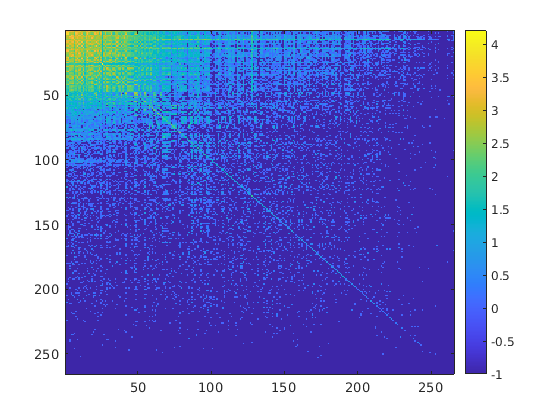

colorbar

Reduce to giant strongly-connected component (losing about 10 nodes)

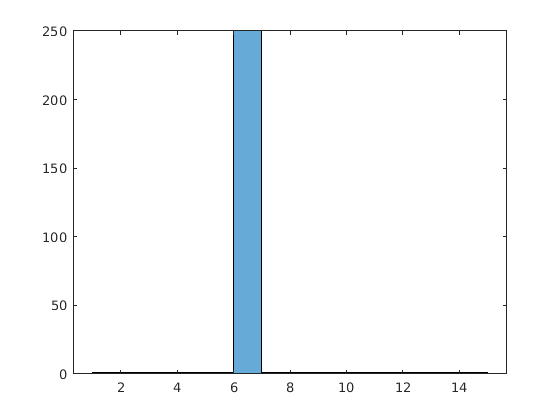

isolated_nodes=[103 104 110 199]; % these are islands

N_S=263;
A=A0(1:N_S,1:N_S);
G=digraph(A);
scc=conncomp(G);
[~,i] = max(histogram(scc,1:(max(scc)+1)).Values);

in_scc = scc==i;
scc_ind = find(in_scc);  
A=A0(in_scc,in_scc);

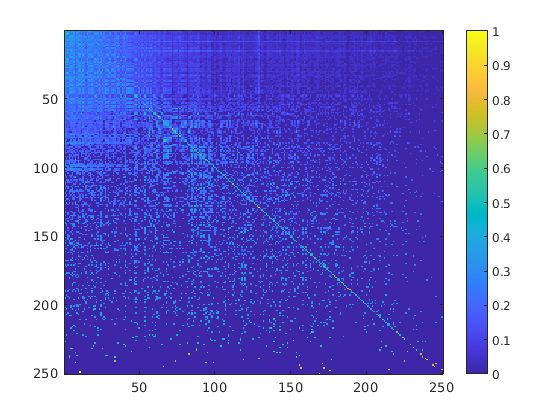

k_out = sum(A,2);
k_in = sum(A,1);
P=diag(k_out.^(-1))*A;
[~,k_ind]=sort(k_out,'descend');
imagesc(P(k_ind,k_ind).^(.333))
colorbar

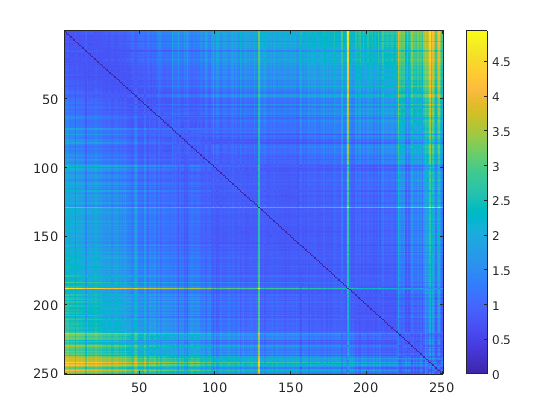

d = -log(get_Ahp(P));
N=size(A,1);
for i=1:N; d(i,i)=0; end

imagesc(d(k_ind,k_ind))
colorbar

Get invariant distribution

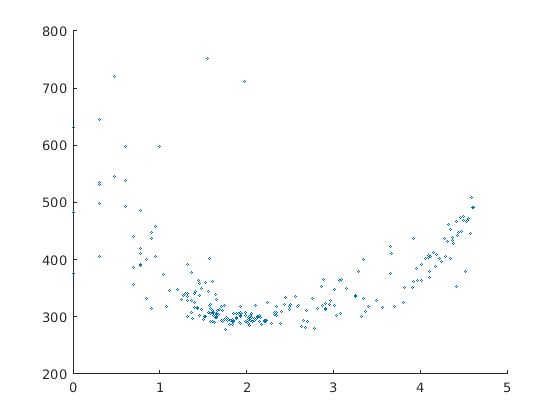

[V,~] = eig(P');
phi = V(:,1);
if phi(1)<0
	phi=-phi;
end
phi=phi/sum(phi);

k_d = sum(d,2);
figure
scatter(log10(k_out),k_d,1)

The upper left group includes a big chunk of Staten Island and about as many other nodes, mostly from Queens.

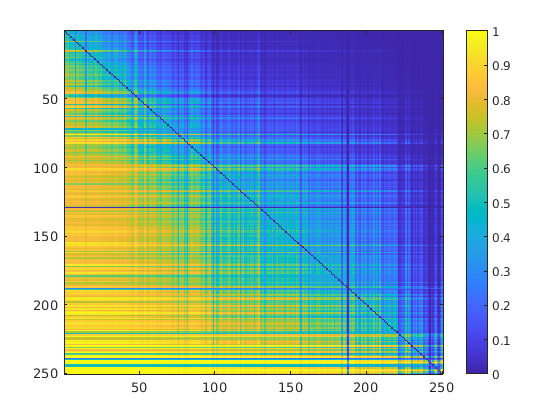

Q = HittingTimes_L3(P);
imagesc(Q(k_ind,k_ind));
colorbar;

Import georgraphy data

S=shaperead('taxi_zones/taxi_zones.shp');
N_S = 263; % number of geographic regions
x = zeros(N_S,1);
y = zeros(N_S,1);
b = zeros(N_S,1);
for i=1:N_S
	x(i) = median(S(i).X,'omitnan');
	y(i) = median(S(i).Y,'omitnan');
	b(i) = median(S(i).borough);
end
[~,~,b]=unique(b);
boros={'EWR','Staten Island','Manhattan','Queens','Brooklyn','Bronx'};

S

S = 263×1 struct array with fields:
    Geometry
    BoundingBox
    X
    Y
    OBJECTID
    Shape_Leng
    Shape_Area
    zone
    LocationID
    borough


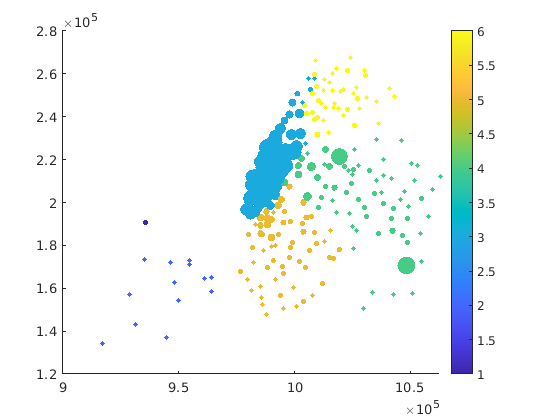

N_A=numel(x(in_scc));
scatter(x(in_scc)',y(in_scc),sqrt(100+k_out),b(in_scc),'filled');
colorbar

N_t = 265; % number of regions referenced in the trip data

## PCA

k_out=sum(A,2);
assert(min(k_out)>0);
[~,sc]=pca(d);

Now, pca with size by degree and color by boro.

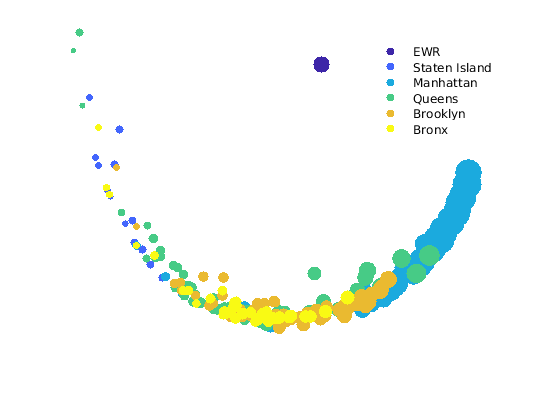

clf
bb=b(in_scc);
for i=1:6
    iind=bb==i;
    scatter(sc(iind,1),sc(iind,2),12*(1+k_in(iind)).^.33,bb(iind),'filled')
    hold on
end
axis off
legend(boros)
legend boxoff

clf

Check out the outliers

[~,zz]=min(vecnorm(sc(:,1:2)-[2.146 21.55],2,2));
S(scc_ind(zz))

ans = struct with fields:
       Geometry: 'Polygon'
    BoundingBox: [2×2 double]
              X: [1×233 double]
              Y: [1×233 double]
       OBJECTID: 1
     Shape_Leng: 0.1164
     Shape_Area: 7.8231e-04
           zone: 'Newark Airport'
     LocationID: 1
        borough: 'EWR'


[~,zz]=min(vecnorm(sc(:,1:2)-[1.692 .2891],2,2));
S(scc_ind(zz))

ans = struct with fields:
       Geometry: 'Polygon'
    BoundingBox: [2×2 double]
              X: [1×118 double]
              Y: [1×118 double]
       OBJECTID: 193
     Shape_Leng: 0.0655
     Shape_Area: 1.4559e-04
           zone: 'Queensbridge/Ravenswood'
     LocationID: 193
        borough: 'Queens'


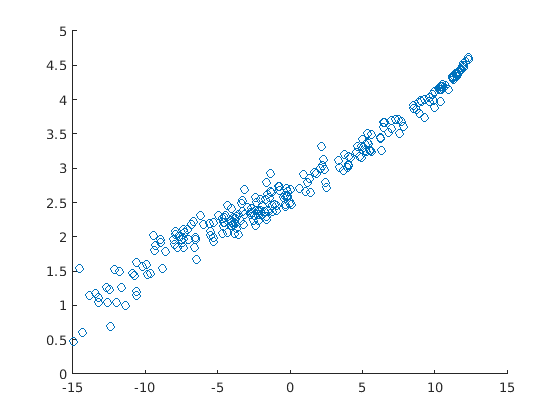

scatter(sc(:,1),log10(k_in))

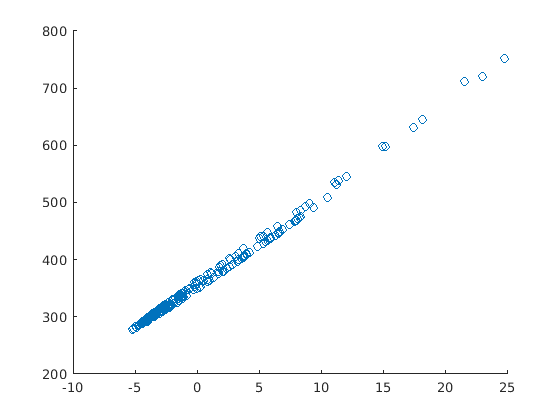

scatter(sc(:,2),k_d)

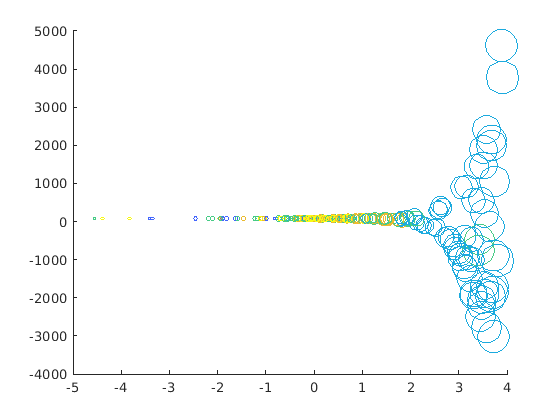

[~,sc_]=pca(A);
scatter(log10(sc_(:,1)-min(sc_(:,1))),sc_(:,2),3*sqrt(1+k_out),b(in_scc))

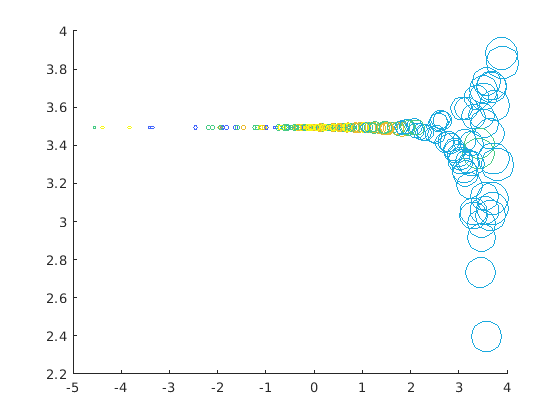

scatter(log10(sc_(:,1)-min(sc_(:,1))),log10(sc_(:,2)-min(sc_(:,2))),3*sqrt(1+k_out),b(in_scc))

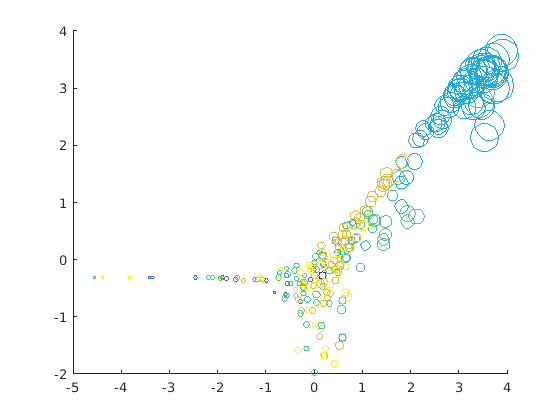

scatter(log10(sc_(:,1)-min(sc_(:,1))),log10(abs(sc_(:,2)-median(sc_(:,2)))),3*sqrt(1+k_out),b(in_scc))

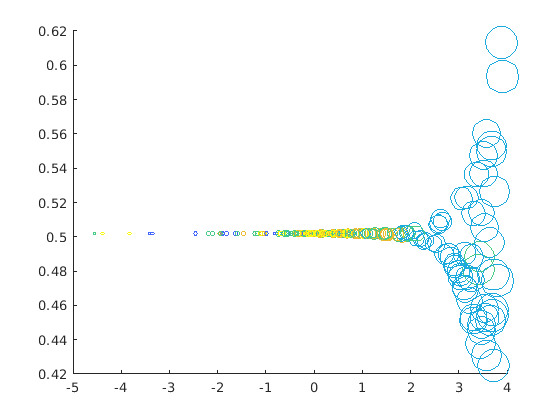

scatter(log10(sc_(:,1)-min(sc_(:,1))),1./(1+exp(-.0001*sc_(:,2))),3*sqrt(1+k_out),b(in_scc))

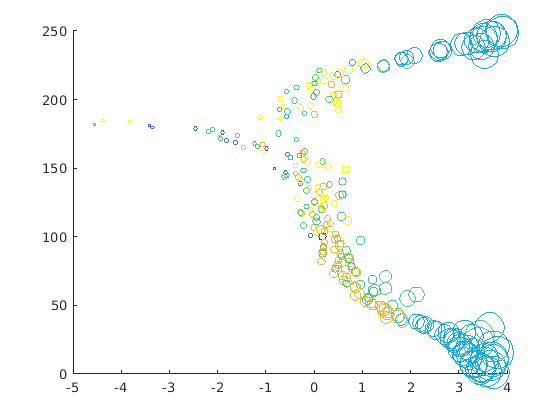

[~,sc2ind]=sort(sc_(:,2));
sc2indinv(sc2ind)=1:length(sc2ind);
scatter(log10(sc_(:,1)-min(sc_(:,1))),sc2indinv,3*sqrt(1+k_out),b(in_scc))

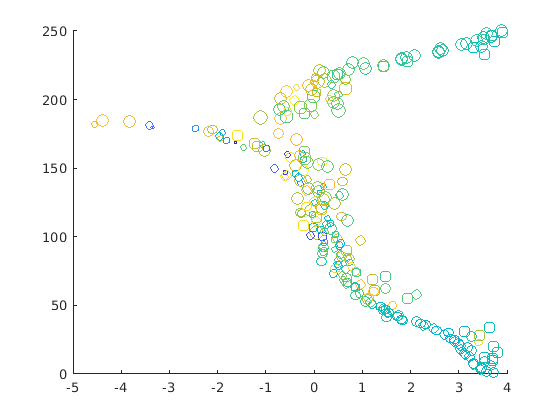

scatter(log10(sc_(:,1)-min(sc_(:,1))),sc2indinv,100*(y(in_scc)-min(y))/(max(y)-min(y)),x(in_scc))

THIS! for Manhattan only, plotting the log PC1 versus PC2 coloring by x coordinate, sizing by y coordinate. The second PC tracks spatial distribution among the large Manhattan neighborhoods (but not the small ones, which are uncorrelated like the other NYC nodes. Because the island is long, the x and y are correlated.

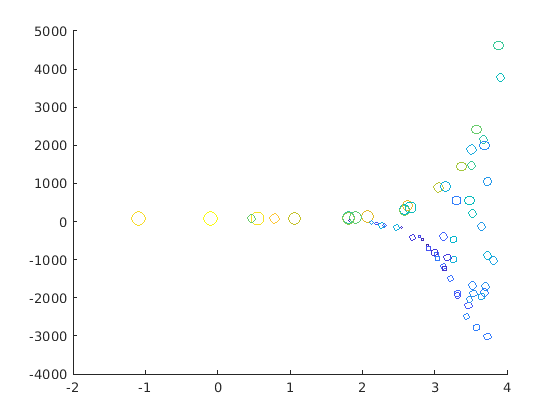

scatter(log10(sc_(bb==3,1)-min(sc_(bb==3,1))),sc_(bb==3,2),100*(y(b==3 & in_scc(1:263)')-min(y(b==3 & in_scc(1:263)')))/(max(y(b==3 & in_scc(1:263)'))-min(y(b==3 & in_scc(1:263)')))+1,x(b==3 & in_scc(1:263)'))

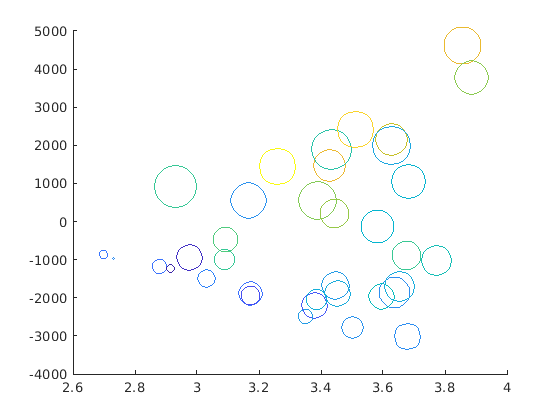

tind =  k_out - min(k_out) > 10000 & bb==3;
yy=y(in_scc);
xx=x(in_scc);
scatter(log10(sc_(tind,1)),sc_(tind,2),1000*(yy(tind)-min(yy(tind)))/(max(yy(tind))-min(yy(tind)))+1,xx(tind))

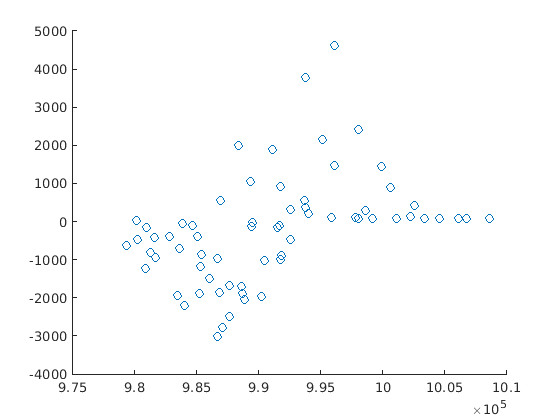

scatter(x(b==3 & in_scc'),sc_(bb==3,2))

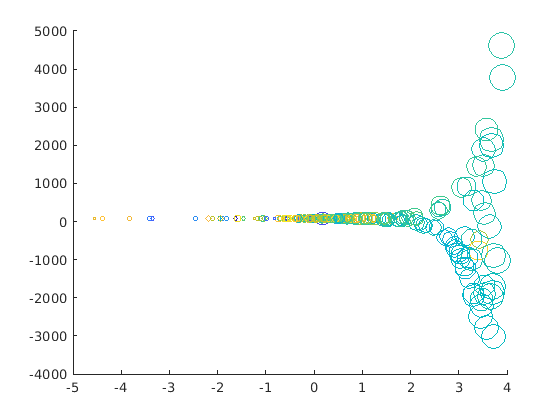

scatter(log10(sc_(:,1)-min(sc_(:,1))),sc_(:,2),2*sqrt(k_in),x(in_scc))

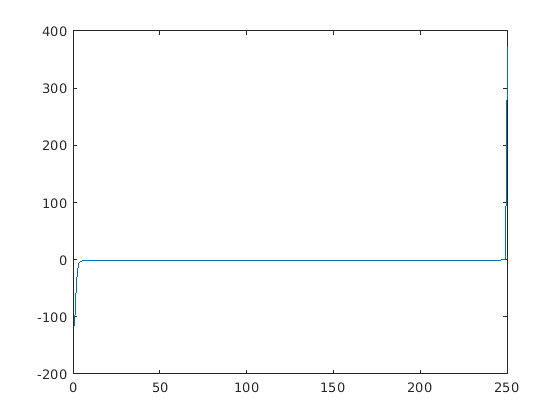

[V,D]=eig(d);
D=diag(D);
plot(sort(D));

## Sort A by boro

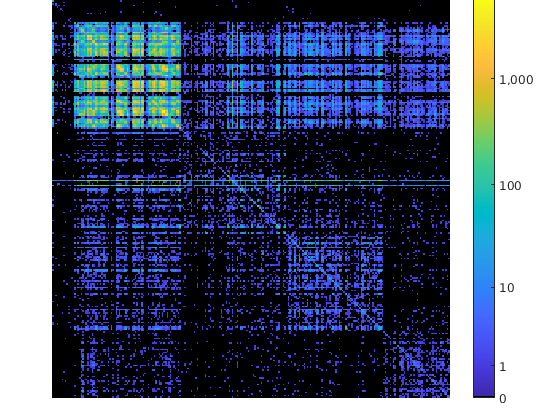

ind = [find(bb==1); find(bb==2); find(bb==3); find(bb==4); find(bb==5); find(bb==6)]';
clf
imagesc(log10(1+A(ind,ind)))
axis square off
colorbar('Ticks',[0, log10(2), log10(11), log10(101), log10(1001), log10(10001)],'TickLabels',["0","1","10","100","1,000","10,000"])
c=colormap;
c(1,:)=0;
addpath('./util');
strip_margins()
colormap(c);

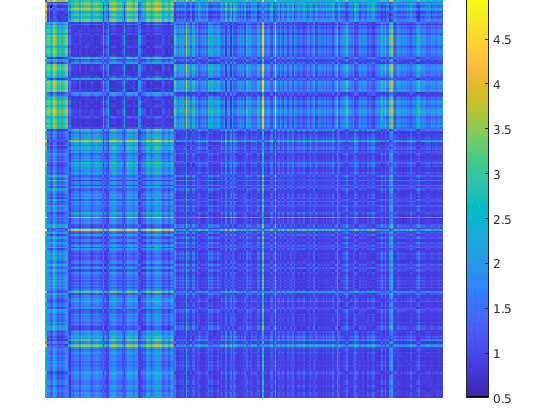

dd=d;
for i=1:N_A; dd(i,i)=1; end
clf
imagesc(dd(ind,ind))
axis square off
strip_margins()
colorbar

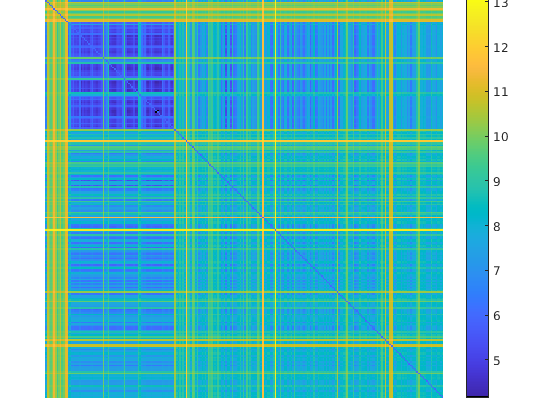

d1=-log(get_Ahp(P,1));
for i=1:N_A; d1(i,i)=0; end
dd=d1;
for i=1:N_A; dd(i,i)=6; end
clf
imagesc(dd(ind,ind))
axis square off
strip_margins()
colorbar

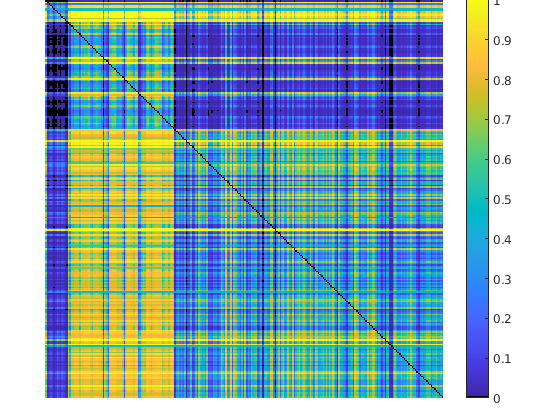

imagesc(Q(ind,ind))
axis square off
colorbar

## Graph visualization

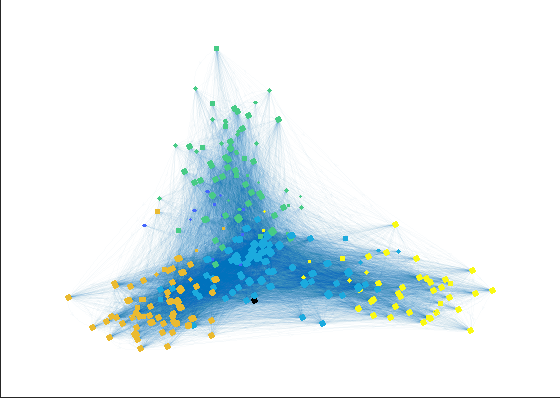

G=digraph(A,'OmitSelfLoops');
G.Nodes.NodeColors=b(in_scc);
p=plot(G);
p.NodeCData=G.Nodes.NodeColors;
p.LineWidth = .1*G.Edges.Weight/max(G.Edges.Weight);
p.MarkerSize = .5*sqrt(1+G.indegree);
p.EdgeAlpha=.02;

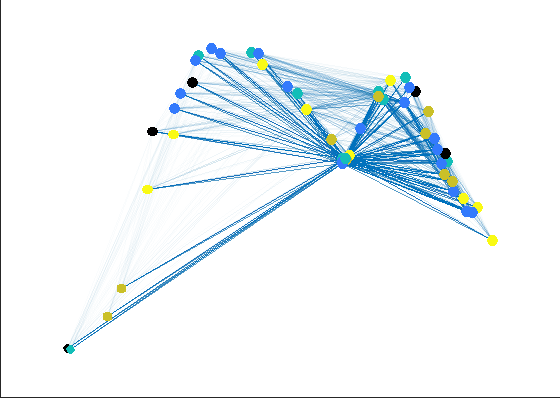

%G=graph(d<3.5,'OmitSelfLoops');
G=graph(d(2:end,2:end)<3,'OmitSelfLoops');
G.Nodes.NodeColors=b(in_scc(2:end));
p=plot(G);
p.NodeCData=G.Nodes.NodeColors;
p.MarkerSize = .5*sqrt(1+G.degree);
p.EdgeAlpha=.02;